Caleb Jacobs, Skylar Callis, Karisa Steffens

# Problem 1:

## (a)


$$p_1  = 5$$



$$p_2 = 2$$



$$p_1 + p_2 = 8$$


where $p_1$ and $p_2$ are the package weights. The system in the form $Ax=b$ is


$$\pmatrix{1 & 0\cr 0 & 1\cr 1 & 1}\pmatrix{p_1 \cr p_2} = \pmatrix{5 \cr 2 \cr 8}$$


where $A$ is a $3\times 2$ matrix, $x$ is a $2\times 1$ column vector, and $b$ is a $3\times 1$ column vector.

## (b)

The vector $b$ is not in the range of $A$ because $b$ can not be written as a linear combination of the columns of $A$.

## (c)

% Define our stuff
A = [1,0;0,1;1,1];
b = [5;2;8];

% Solve normal equations
x = (A'*A)\(A'*b)

x =     5.3333
    2.3333


After computing the weights, we can conclude that we either underestimated the weights of the packages or the post office overestimated the weights of the packages. Furthermore, if the scales round to the nearest pound, then our scale readings do agree with the post office's scale.

## (d)

% Solve the least squares problem using QR
[Q,R] = qr(A,0);
Qb = Q'*b;
x = backwardSub(R,Qb)

x =     5.3333
    2.3333


Using QR with backward substitution gave us the same solution as part c.

# Problem 2:

## (a)

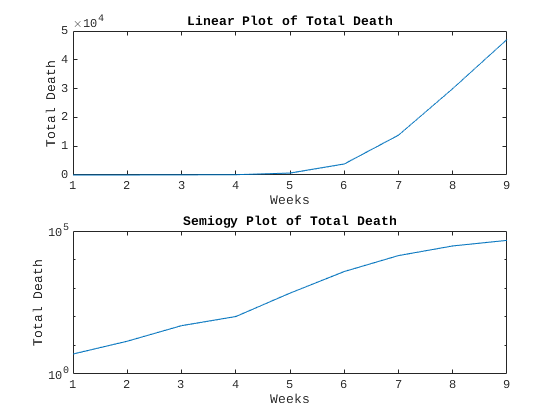

% Store data
deaths = [5;14;49;102;673;3825;13836;30008;47060];
weeks = (1:9)';

figure()
subplot(2,1,1)
plot(weeks,deaths)
title('Linear Plot of Total Death')
xlabel('Weeks')
ylabel('Total Death')

subplot(2,1,2)
semilogy(weeks,deaths)
title('Semiogy Plot of Total Death')
xlabel('Weeks')
ylabel('Total Death')

The first plot appears to show an exponential trend in our data. To confirm that the trend is exponential, we used semilogy in the second plot. The semilogy plot is roughly linear and so our data must be roughly exponential. So we can try fitting an exponential model to our data.

## (b)


$$y_i = a_1 e^{a_2 x_i} \Rightarrow \log{y_i} = \log{a_1} + a_2 x_i$$


% Compute the A and b components of our exponential 
% least squares problem
A = [ones(length(deaths),1), weeks];
b = log(deaths);

% Solve the least squares problem using QR
[Q,R] = qr(A,0);
Qb = Q'*b;
x = backwardSub(R,Qb);

% Compute a1 in our model
a1 = exp(x(1))

a1 = 1.2825

% Compute a2 in our model
a2 = x(2)

a2 = 1.2420

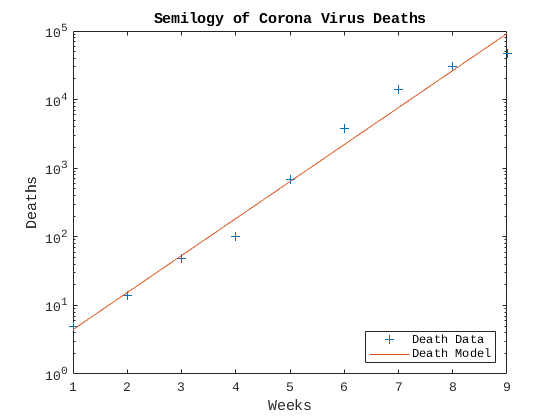

% Plot our model over a few weeks
xs = linspace(1,9,100);

figure()
semilogy(weeks, deaths,'+')
hold on
semilogy(xs, a1*exp(a2*xs))
title('Semilogy of Corona Virus Deaths')
xlabel('Weeks')
ylabel('Deaths')
legend('Death Data','Death Model',"Location","southeast")

The equation for our model is $f(t) = 1.2825 \cdot e^{1.2420 t}$. To make our plot easier to read, we used semilogy to make the model and data linear. Looking at the plot, our model appears to follow the data accurately. The model is accurate because roughly half of the data lies above and below our model and the data doesn't deviate too far from the model. 

## (c)

week15deaths = a1*exp(a2*15)

week15deaths = 1.5813e+08

Using our model, the estimated number of deaths in week 15 is 150 million; this is unreasonable even if preventative measures were never taken. If this many people did die, only about half of the US would still be alive. The model is inaccurate because we are trying to extrapolate to week 15 when we are only given data up to week 9. Furthermore, exponential growth only models the early stages of infection which doesn't account for the number of people that you can still be infected. 

# Problem 3:

## Given $P = \hat{Q}\hat{Q}^T$ and $A = \hat{Q}\hat{R}$ prove the following:

## (a)


$$A A^\dagger = A(A^T A)^{-1} A^T$$
 


$$= \hat{Q}\hat{R}((\hat{Q}\hat{R})^T \hat{Q}\hat{R})^{-1} (\hat{Q}\hat{R})^T$$
 


$$=\hat{Q}\hat{R} ( \hat{R}^T\hat{Q}^T \hat{Q}\hat{R})^{-1} \hat{R}^T\hat{Q}^T$$


because $\hat{Q}$ is orthonormal $\hat{Q}^T\hat{Q} = I$ and so


$$=\hat{Q}\hat{R}(\hat{R}^T\hat{R})^{-1} \hat{R}^T\hat{Q}^T$$


because $\hat{R}$ is upper triangular, $\hat{R}$ is invertible


$$=\hat{Q}\hat{R}\hat{R}^{-1}(\hat{R}^T)^{-1} \hat{R}^T\hat{Q}^T$$


$= \hat{Q}\hat{Q}^T = P$.

## (b)


$$P^2 = PP = \hat{Q}\hat{Q}^T \hat{Q}\hat{Q}^T = \hat{Q} I \hat{Q}^T = \hat{Q}\hat{Q}^T = P.$$


## (c)

We are given $u = Px$ and $v = (I - P)x$. Then


$$u \cdot v = u^T v$$
 


$$= (Px)^T (I-P)x$$
 


$$= x^T P^T (I-P)x$$
 


$$= x^T P^T x - x^T P^T Px$$
 


$$= x^T P^T x -  x^T (\hat{Q}\hat{Q}^T)^T \hat{Q}\hat{Q}^T x$$



$$= x^T P^T x - x^T \hat{Q}\hat{Q}^T \hat{Q}\hat{Q}^T x$$


$= x^T P^T x - x^T P^2 x = 0$. 

function x = backwardSub(U, b) 
    % Get size of U
    n = length(U);
    
    % Initialize solution vector and then solve using backward substitution
    x = zeros(n,1);
    for i = n:-1:1
        x(i) = (b(i) - U(i,i+1:n)*x(i+1:n)) / U(i,i);
    end
end